# Measurement and Analysis of Gait

#### OVERVIEW:

In this workbook, we will use motion capture data similar to what we have collected.  The goal is to get some intuition for what motion data looks like, including kinematics and ground reaction forces.  In the following workbooks, we will use some of this data to simulate an exoskeleton or prosthesis controller. 

#### **Let's Begin:**

To start, Inspect the head of the data table, which should have printed below this cell.  Note how each marker (e.g., "R_ASIS", which corresponded to the right Anterior Superior Iliac Spine (pointy hip bone)) has three columns, corresponding to the marker's X, Y, Z locations respectively.  Positive X = "rightward" on the treadmill. Positive Y = "forward" on the treadmill. Positive Z = "Upward."  Also note that COP has only two dimensions, corresponding to X (rightward) and Y (forward).  Finally, see the figure for locations of the markers

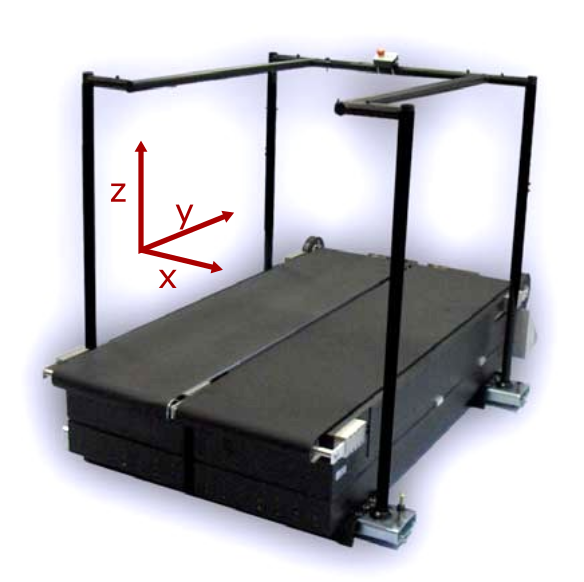

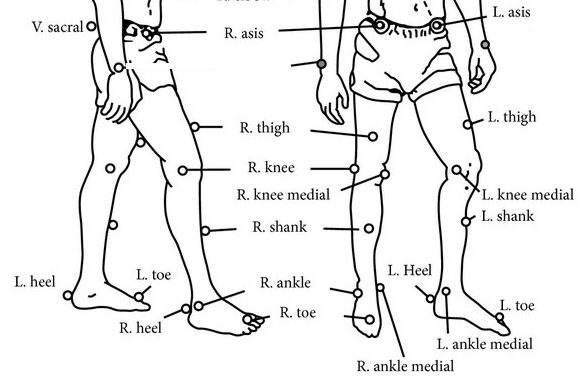

clear; close all; clc
addpath('I_Sensor_Data_Processing/SDP_functions/','Sensor_data/')
filename  = "0deg_1.2ms_tracked"; % Load the intermediate walking speed trial

data = load(filename + ".mat");
temp_ = fieldnames(data);
data = data.(temp_{1});

fs_force    = data.Force.Frequency; % Forceplate sampling frequency
fs_markers  = data.FrameRate; % Marker sampling frequency
fs_delsys   = data.Analog(2).Frequency; % EMG sampling frequency

D   = RepackageMocapData(data, fs_force, fs_markers);
head(D) % Show the top 8 rows of the data table (D)

       Time                 R_ASIS                        L_ASIS                       V_Sacral                   R_Thigh_Front                   R_Knee_Lat                    R_Knee_Med                  R_Shank_Front                     R_Heel                     R_Ankle_Lat                   R_Ankle_Med                    R_Toe_Tip                   L_Thigh_Front                   L_Knee_Lat                    L_Knee_Med                  L_Shank_Front                     L_Heel                     L_Ankle_Lat                   L_Ankle_Med                    L_Toe_Tip                  R_COP               L_COP        

## 1.a

Plotting the anterior/posterior position of the right toe marker (D.R_Toe_Tip) vs time (D.Time). Zooming in to show approximately 3 strides. Labeling axes "Time (s)" and "Height (mm)". 

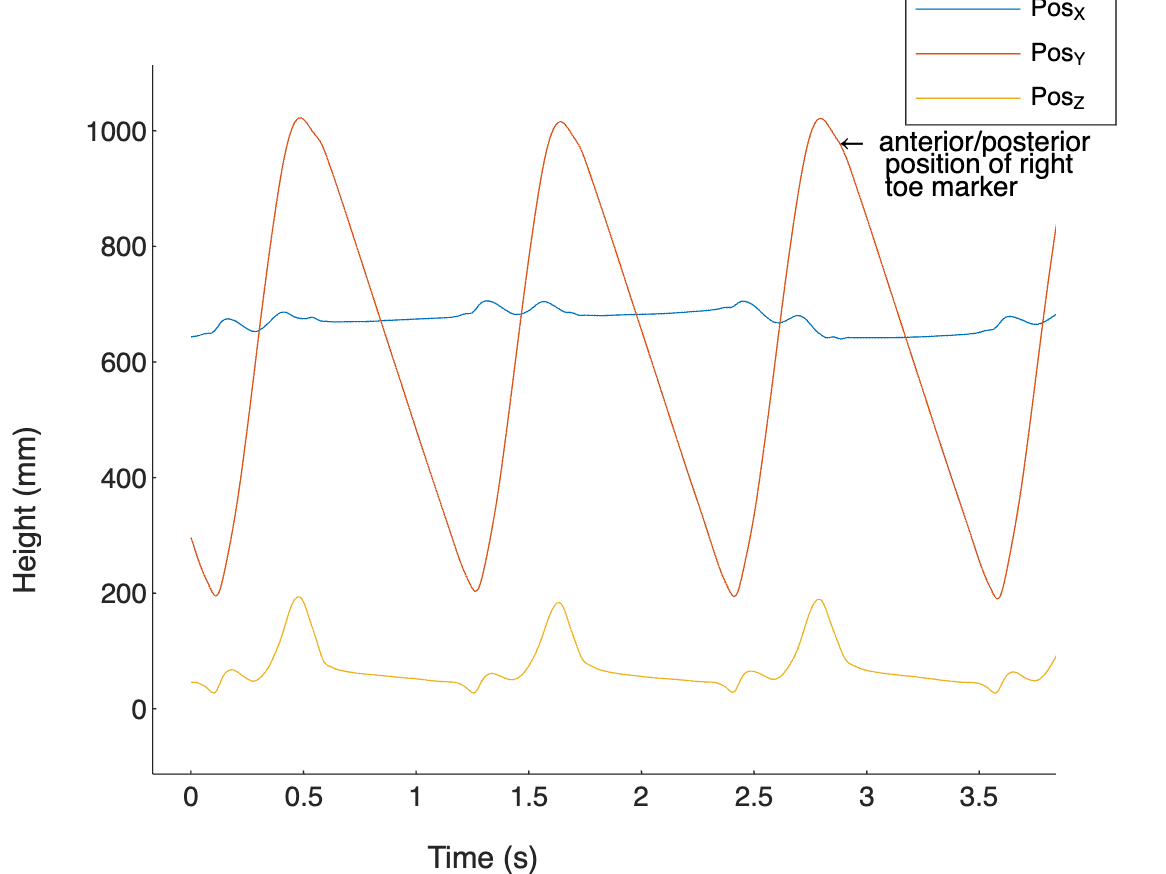

figure; hold on
plot(D.Time,D.R_Toe_Tip) %(1:8000,2)
xlabel("Time (s)")
ylabel("Height (mm)")
legend("Pos_X","Pos_Y", "Pos_Z")

%Zoomed in show 3 strides only
xlim([-0.17 3.84])
ylim([-113 1114])
zlim([-1.00 1.00])

legend("Position", [0.79621,0.87466,0.14286,0.12619])
t1='\leftarrow anterior/posterior';
t2='position of right';
t3='toe marker';
text(2.865,980,t1)
text(3.08,945,t2)
text(3.08,905,t3)

## 1.b

Plot the 3D toe marker trajectories using the "plot3" command.  Label axes. Using the command "axis equal" to make spacing the same for all directions (in fact, we should do that for all plots showing spatial locations!). Rotate the view so that we can get an idea of what the toe trajectories were in space (roughly isometric view). Making sure to label axes, and add a legend. Again make sure to Update Code with our new view.

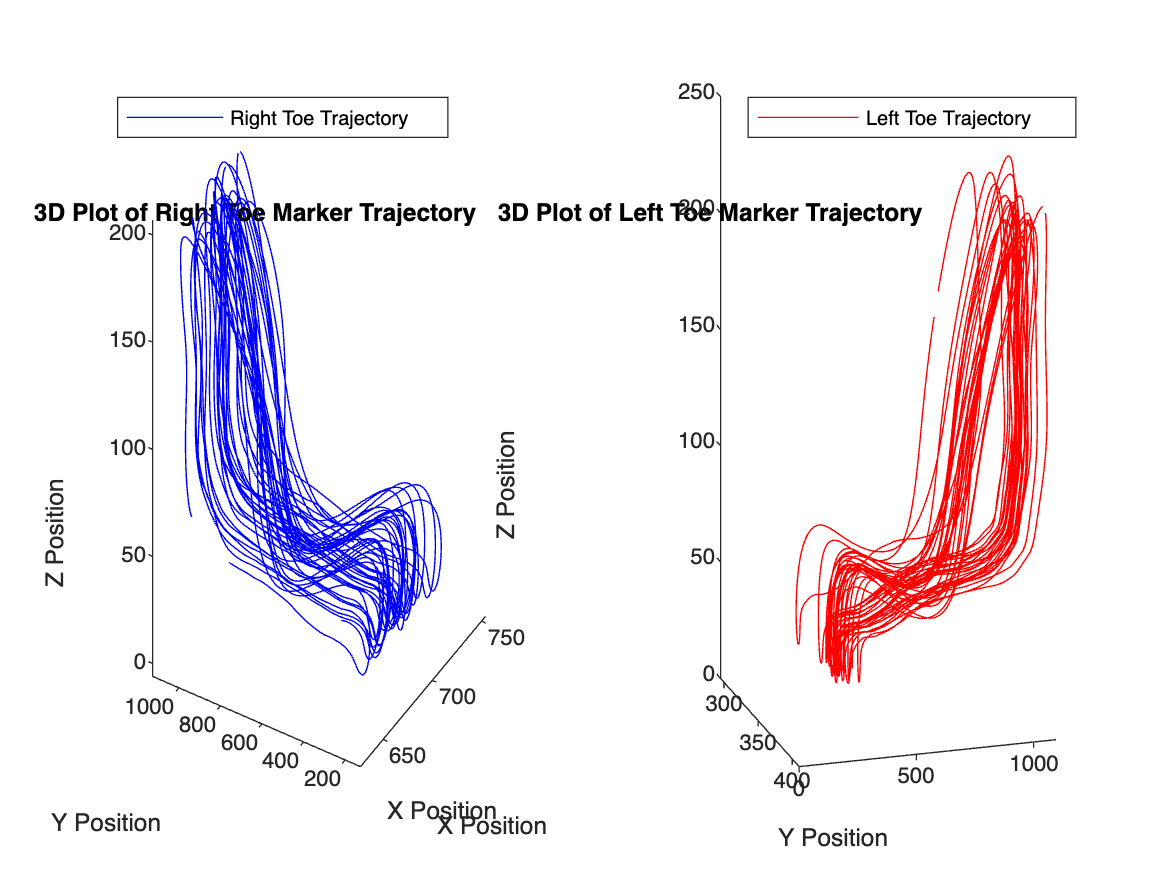

figure; hold on
tiledlayout(2,8)
ax1=nexttile([2 4]);
axis equal

%Right toe plot
plot3(ax1, D.R_Toe_Tip(:,1),D.R_Toe_Tip(:,2),D.R_Toe_Tip(:,3),"blue")
legend(ax1, "Right Toe Trajectory");
title(ax1, "3D Plot of Right Toe Marker Trajectory")
xlabel("X Position")
ylabel("Y Position")
zlabel("Z Position")
% axes 1
xlim([627 754])
ylim([126 1126])
zlim([-6 207])
view([301 21])
legend("Position", [0.1012,0.8431,0.28214,0.045238])

%Left toe Plot
ax2=nexttile([2 4]);
axis equal
plot3(ax2, D.L_Toe_Tip(:,1),D.L_Toe_Tip(:,2),D.L_Toe_Tip(:,3),"red")
title(ax2, "3D Plot of Left Toe Marker Trajectory")
legend(ax2, "Left Toe Trajectory")
xlabel("X Position")
ylabel("Y Position")
zlabel("Z Position")
legend("Position", [0.64088,0.8431,0.28214,0.045238])
% axes 2
xlim([295 410])
ylim([0 1095])
zlim([0 250])
view([73 9])

## 1.c

**Plotting **the sagittal plane (Y-Z) trajectories of the *shank* (plotting a line between the lateral ankle marker and lateral knee marker) and *foot* (plotting a line between the heel marker and toe top) for approximately one stride (approximately the first 350 data points). 

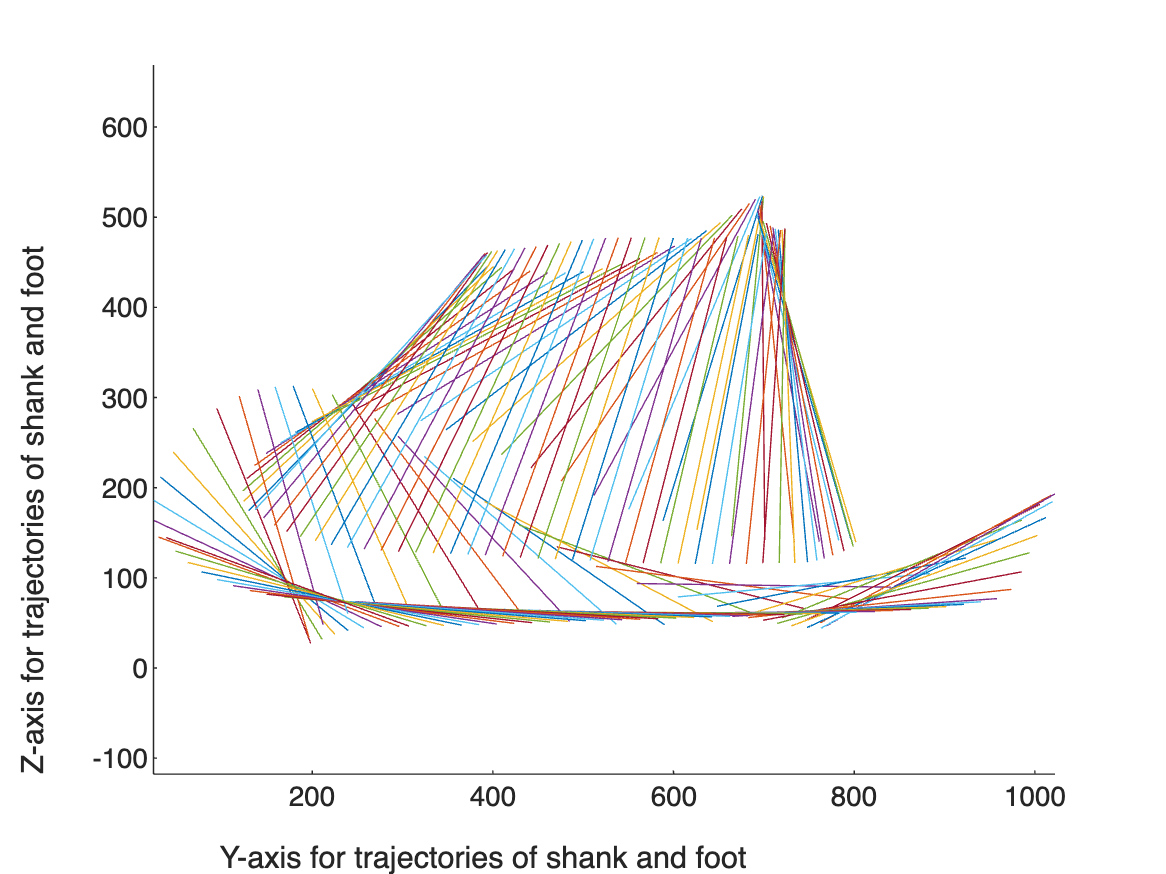

% Shank trajectory
figure, hold on
axis equal
Y1=[D.R_Ankle_Lat(1:5:350,2) D.R_Knee_Lat(1:5:350,2)]; %Y coordinates
Z1=[D.R_Ankle_Lat(1:5:350,3) D.R_Knee_Lat(1:5:350,3)]; %Z cordinates

% Foot trajectory
Y2=[D.R_Heel(1:5:350,2) D.R_Toe_Tip(1:5:350,2)]; %Y coordinates
Z2=[D.R_Heel(1:5:350,3) D.R_Toe_Tip(1:5:350,3)]; %Z cordinates
for i=1:70
    plot(Y1(i,:),Z1(i,:))
    plot(Y2(i,:),Z2(i,:))
    pause(0.01)
end
xlabel("Y-axis for trajectories of shank and foot")
ylabel("Z-axis for trajectories of shank and foot")

## 2.a

An estimate of **sagittal plane** ankle kinematics can be obtained by calculating the angle between the following two lines: lateral ankle – lateral knee, and heel – toe.  

Function “CalculateAnkleAngle” that takes in the data table D, and returns ankle angle, in degrees. Dorsiflexion (from neutral) should be positive, and ankle angle is typically defined as 0° when the foot segment is at a right angle to the shank segment, so making sure to add/subtract a 90 degrees offset angle if needed. Ankle range of motion should approximately -10 deg (plantarflexion) to 25 deg (dorsiflexion).

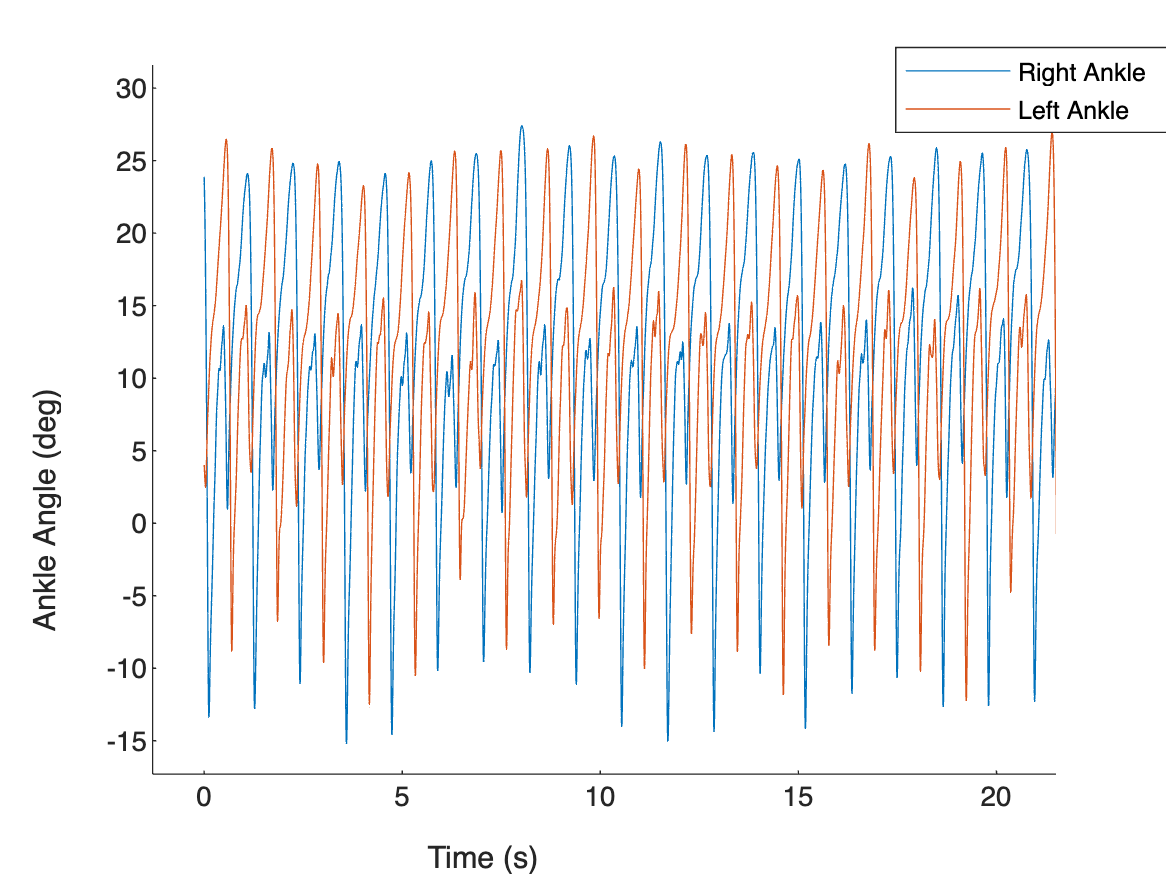

% Do not modify this code. Only modify the CalculateAnkleAngle function
R_Ankle_Angle = CalculateAnkleAngle(D.R_Knee_Lat, D.R_Ankle_Lat, D.R_Toe_Tip, D.R_Heel); 
L_Ankle_Angle = CalculateAnkleAngle(D.L_Knee_Lat, D.L_Ankle_Lat, D.L_Toe_Tip, D.L_Heel);
figure; hold on
plot(D.Time, R_Ankle_Angle)
plot(D.Time, L_Ankle_Angle)
xlabel('Time (s)')
ylabel('Ankle Angle (deg)')
legend(["Right Ankle","Left Ankle"])

xlim([-1.3 21.5])
ylim([-17.3 31.6])
legend("Position", [0.79282,0.85627,0.20179,0.082143])

## 2.c

Modify "CalculateJointVelocity" to calculate angular velocity from joint angle data using Matlab’s “diff” function and the known sampling frequency.  Use the filter flag "do_filter", such that when True, the function filters the velocity data with a 4th order, 10 Hz, zero-lag low-pass butterworth filter using “filtfilt.”

**Plot **compares ankle velocity of the Right Ankle Angle when filtered vs unfiltered.

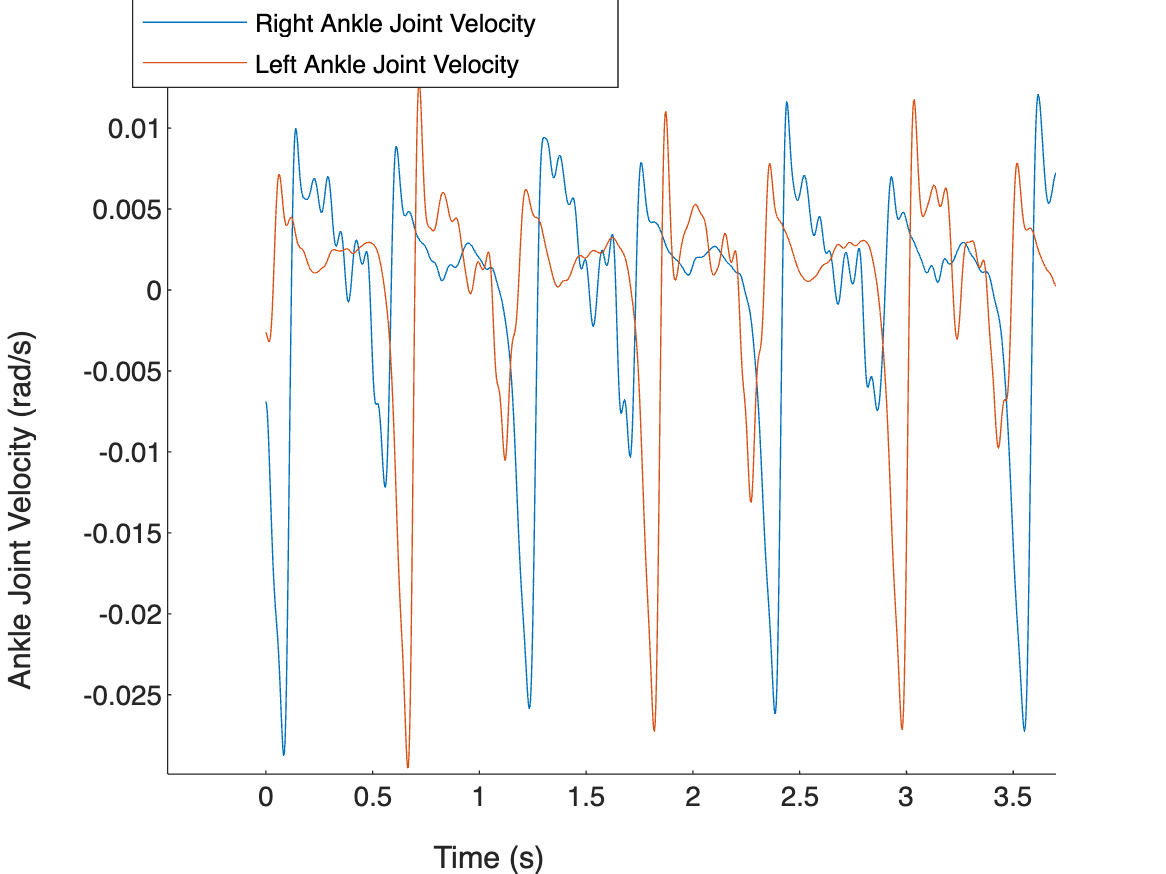

R_AnkleJointVelocity = CalculateJointVelocity(R_Ankle_Angle,10,true);
L_AnkleJointVelocity = CalculateJointVelocity(L_Ankle_Angle,10,true);
figure; hold on
plot(D.Time(1:size(R_AnkleJointVelocity,1)), R_AnkleJointVelocity)
plot(D.Time(1:size(L_AnkleJointVelocity,1)), L_AnkleJointVelocity)
xlabel('Time (s)')
ylabel('Ankle Joint Velocity (rad/s)')
legend("Right Ankle Joint Velocity","Left Ankle Joint Velocity")

xlim([-0.46 3.70])
ylim([-0.0299 0.0139])
legend("Position", [0.15611,0.90918,0.33214,0.082143])

## 3.a

Plot the right treadmill belt's vertical ground reaction force vs Time and the anterior/posterior ground reaction force vs Time (on the same plot.)  *Note*: Treadmill force is in N.  Zoom into approximately three strides. 

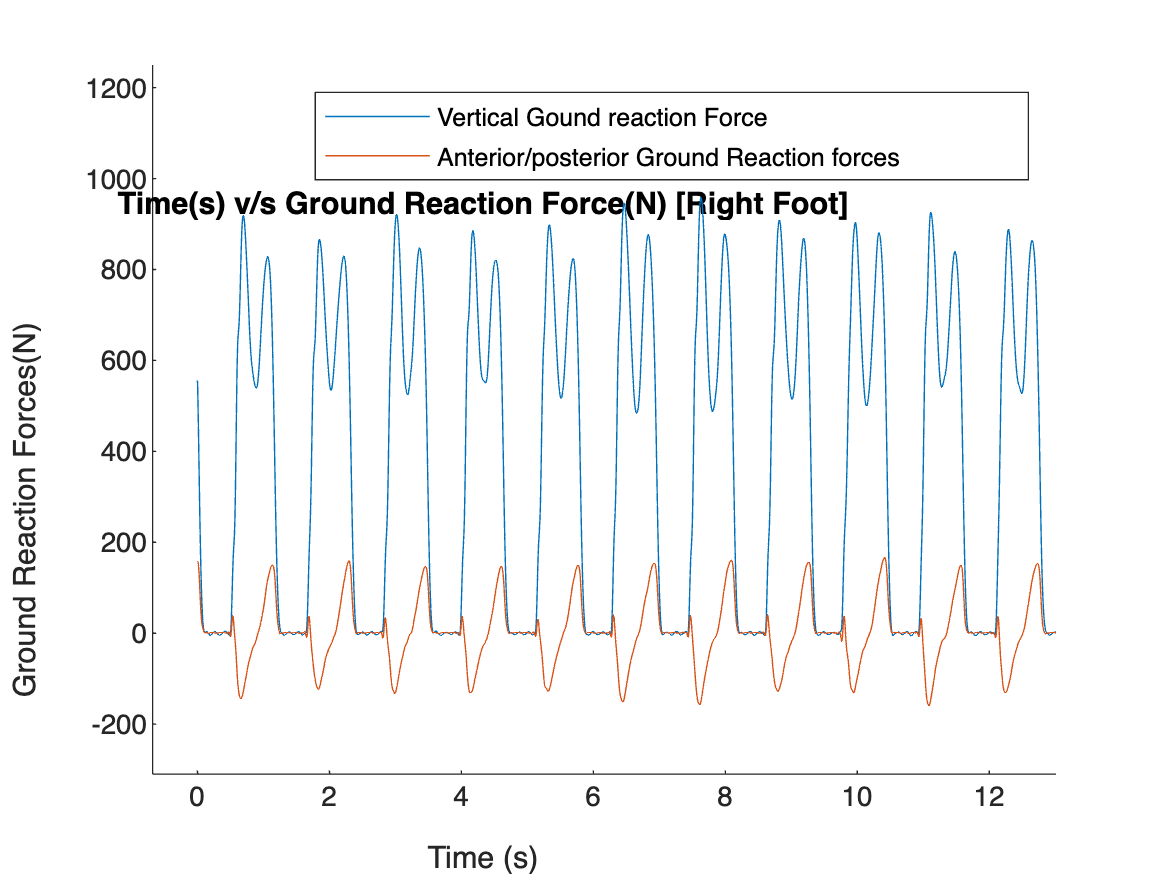

figure; hold on
plot(D.Time,D.R_F(:,3)) %vertical force resolved in the Z-direction
plot(D.Time,D.R_F(:,2))%anterior/posterior force resolved in the Y-direction
title("Time(s) v/s Ground Reaction Force(N) [Right Foot]")
legend("Vertical Gound reaction Force","Anterior/posterior Ground Reaction forces")
xlabel('Time (s)')
ylabel('Ground Reaction Forces(N)')

xlim([-0.68 13.01])
ylim([-310 1250])
zlim([-1.00 1.00])

## **3.b**

Generating a figure of the GRF vector relative to the ankle. 

Note: *COP_relative_to_ankle_in_AP* describes where the center of pressure is relative to the ankle axis (as defined by the ankle marker), in the anterior-posterior direction. We will use this variable in the next cell to calculate ankle torque. 

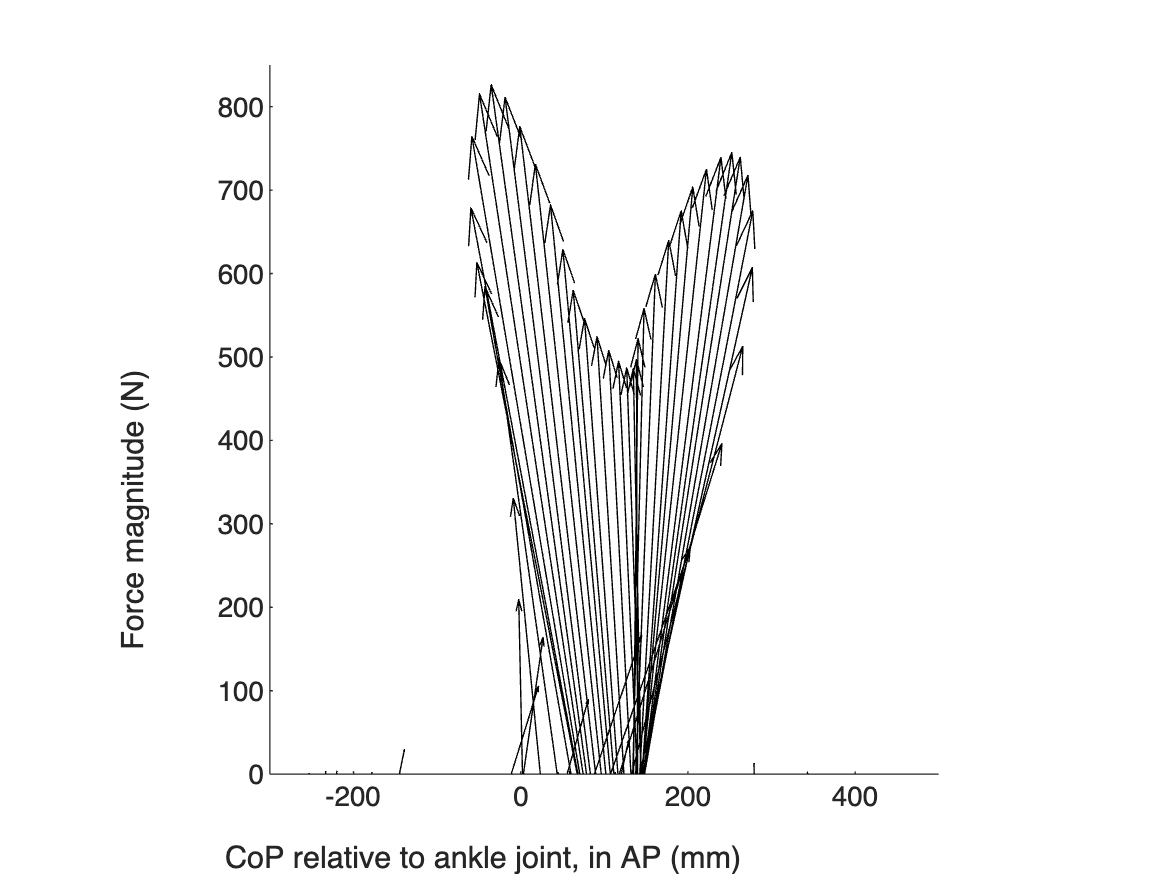

% Do not modify this cell
COP_relative_to_ankle_in_AP = D.R_COP(:,2) - D.R_Ankle_Lat(:,2);
figure; hold on
axis equal
xlabel('CoP relative to ankle joint, in AP (mm)')
ylabel('Force magnitude (N)')
xlim([-300,500])
ylim([0,850])
for i = 50:5:400
    quiver(COP_relative_to_ankle_in_AP(i), 0, D.R_F(i,2), D.R_F(i,3), 'k')
    pause(0.01)
end    

## 3.c

The ankle torque can be determined by considering the force applied to the foot segment.  We will make a couple simplifications: 1) ignore medial/lateral motions, and use only the **sagittal plane kinematics and GRFs**, 2) ignore foot mass and inertia in this calculation. Use both the vertical and horizontal components of the GRF, as well as the moment arms between ankle location and force vector location.  

*Note*: center of pressure is only defined when a force exists (i.e. when force is non-zero), but we still have small, stray numbers for the COP during swing.  Use a threshold on vertical GRF of 50 N such that during swing phase, ankle torque is defined as 0. 

*Note 2:* One of the confusing things about this type of analysis is the sign conventions.  The GRF is applying an EXTERNAL moment about the ankle joint.  But we are interested in the INTERNAL ankle moment--that is, the moment created by our muscles pulling.  The INTERNAL moment is equal and opposite to the EXTERNAL moment in this static case. We're going to call an **internal** **dorsiflexion** **torque positive** (the red arrow is showing the INTERNAL moment.)

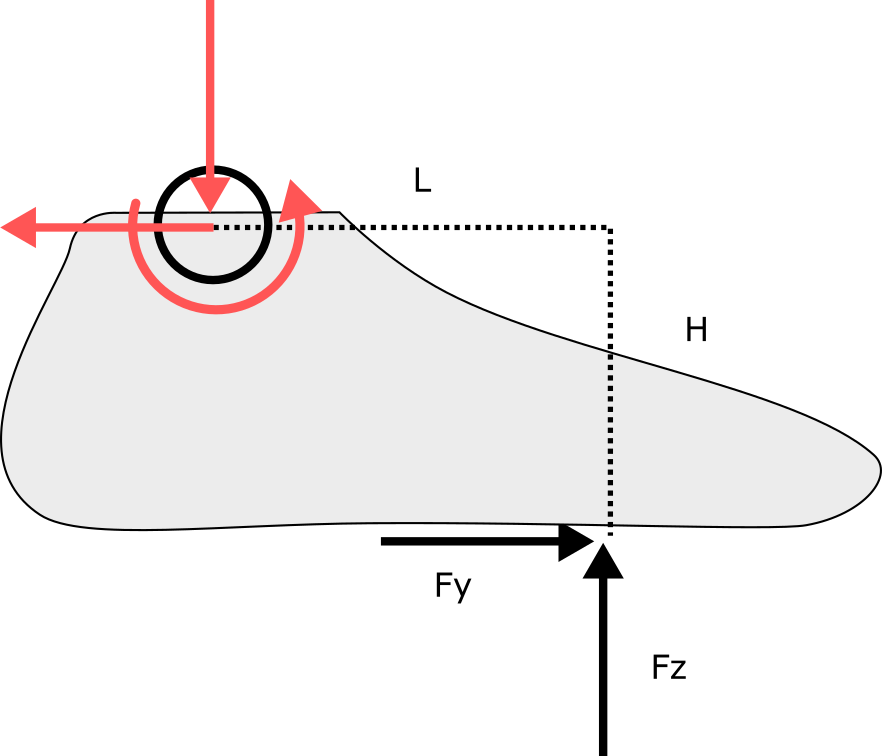

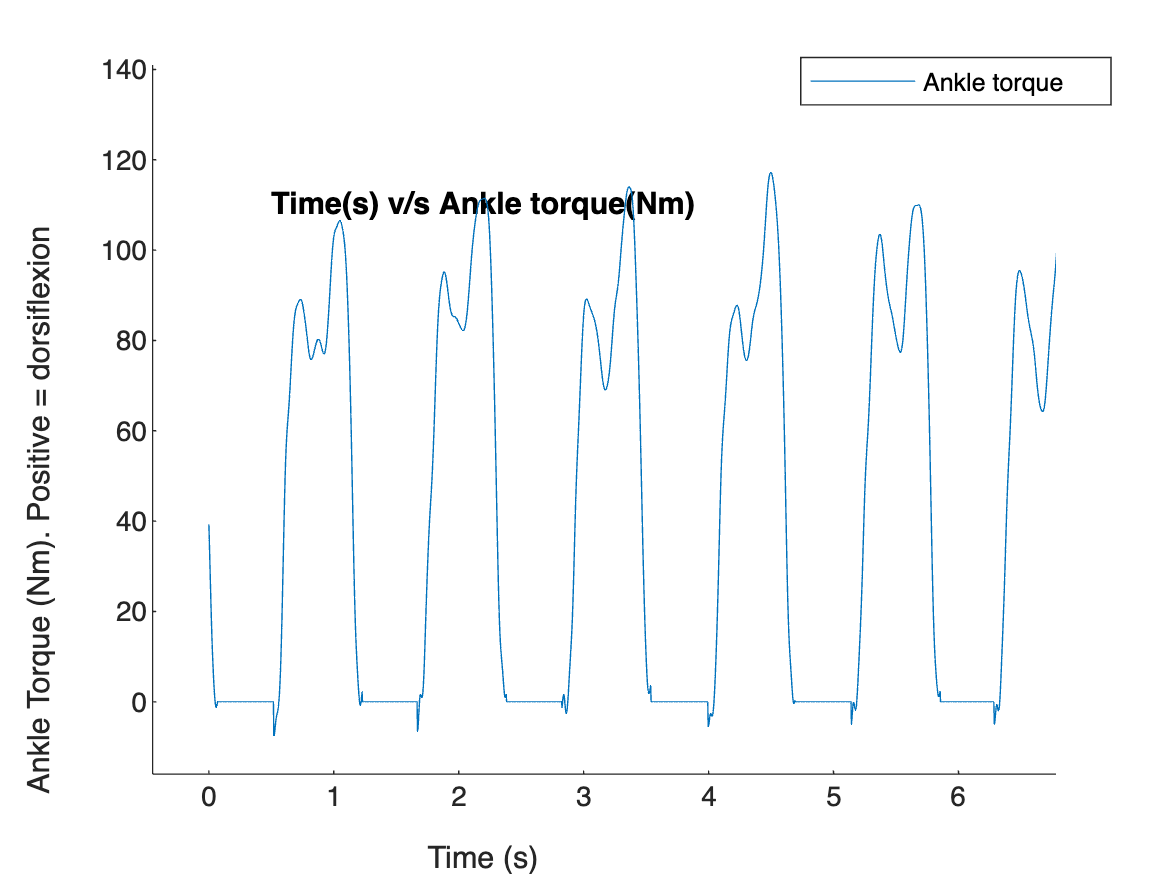

% Do not modify code; only modify CalculateAnkleTorque
mm_to_m = 0.001; % Markers are in mm but we need them in standard metric units (m)
R_Ankle_Torque = CalculateAnkleTorque(D.R_F(:, 2), D.R_F(:,3), COP_relative_to_ankle_in_AP*mm_to_m, D.R_Ankle_Lat(:,3)*mm_to_m);
R_Ankle_Torque(D.R_F(:,3)<50) = 0;

figure; hold on
plot(D.Time, R_Ankle_Torque)
ylabel('Ankle Torque (Nm). Positive = dorsiflexion')
xlabel('Time (s)')
legend('Ankle torque')
title('Time(s) v/s Ankle torque(Nm)')


legend("Position", [0.71385,0.88471,0.2125,0.045238])
xlim([-0.45 6.78])
ylim([-16 141])

## 3.d

Why were the assumptions we made reasonable for the ankle, but not the knee? What is a task for which this would not have been a reasonable assumption at the ankle?

*1) During the swing motion of walking gait, the ankle is applying any forces as it is neither in contact with the ground nor is transfering any motion for that phase.*

*2) Hence, our assumption that it is zero is plausible, extent to the human not putting in an unecessary deliberate motion.*

*3) However, in case of knee, torque is continually required throughtout the stance and swing phase for:*

*    a) loading and pushing the body forward during the late stance phase,*

*    b) rotating the knee to take the stride forward for the next heel-in,*

*    c) stiffening the knee after its complete extension topull the body weight forward.*

*4) On the contrary, tasks such as Running require the toe-in where the Center Of Pressure gets pushed forward and the Ground reaction force balancing is highly dependent on the ankle torque and stiffness.*

*5) Additionally, Foot mass and inertia are considered important where walking on uneven terrain or whan people have disorders such as crouch gait, excessive pronation,etc.*

## 3.X

Calculate and plot Ankle Power in Watts.  Zooming in to show three strides.

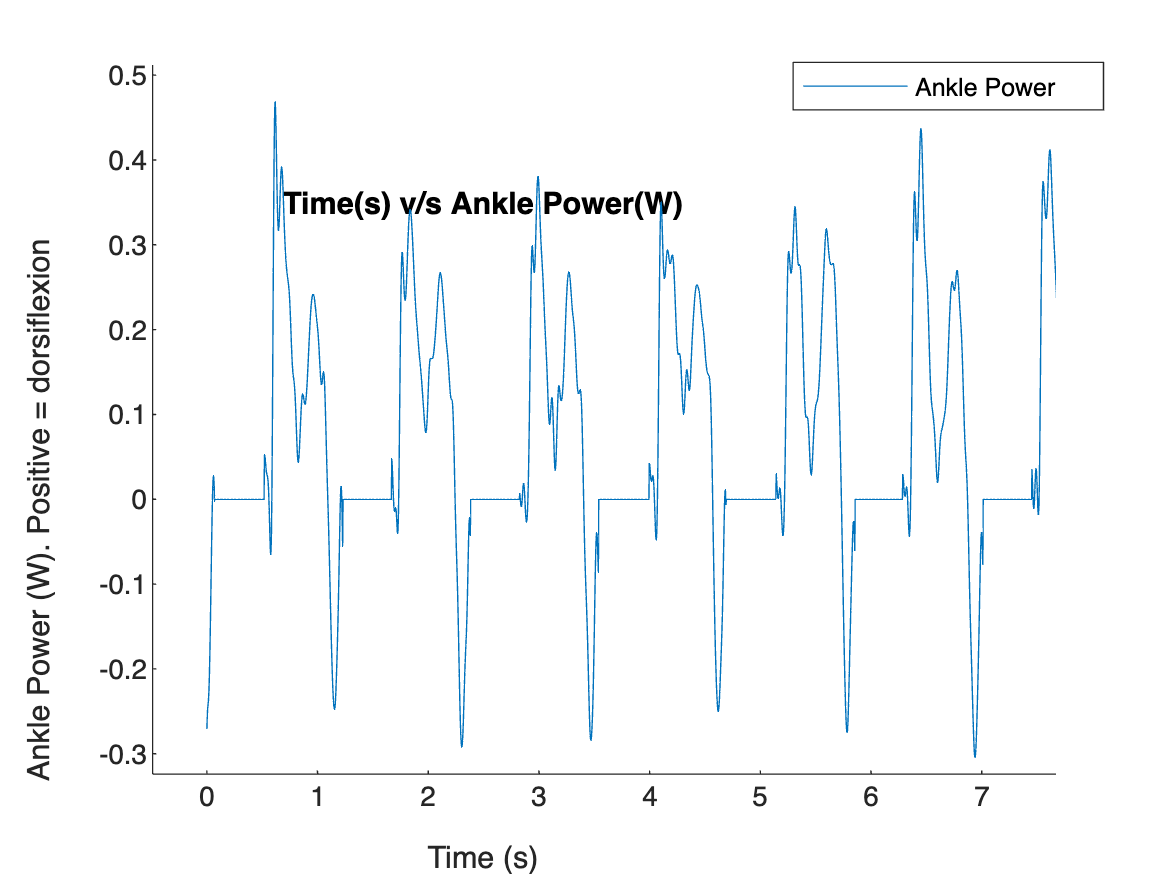

% Put your code here
R_AnklePower=R_Ankle_Torque(1:size(R_AnkleJointVelocity,1)).*R_AnkleJointVelocity;
figure; hold on
plot(D.Time(1:size(R_AnkleJointVelocity,1)), R_AnklePower)
ylabel('Ankle Power (W). Positive = dorsiflexion')
xlabel('Time (s)')
legend('Ankle Power')
title('Time(s) v/s Ankle Power(W)')

xlim([-0.49 7.67])
ylim([-0.324 0.512])

legend("Position", [0.7075,0.87836,0.2125,0.045238])

## 4.a

Modified"GetHeelStrikes.m" to calculate heel strike indices using a threshold of 50 N on vertical force.  The function should return a vector containing the indices at which heel strike occurred.  Similarly, modify "GetToeOffs.m" to calculate toe offs using the same threshold value. Plotting  heel strike and toe off indices relative to the vertical ground reaction force. 

*Note: heel strike occurs if the vertical force was previously not above the threshold, but is now... *

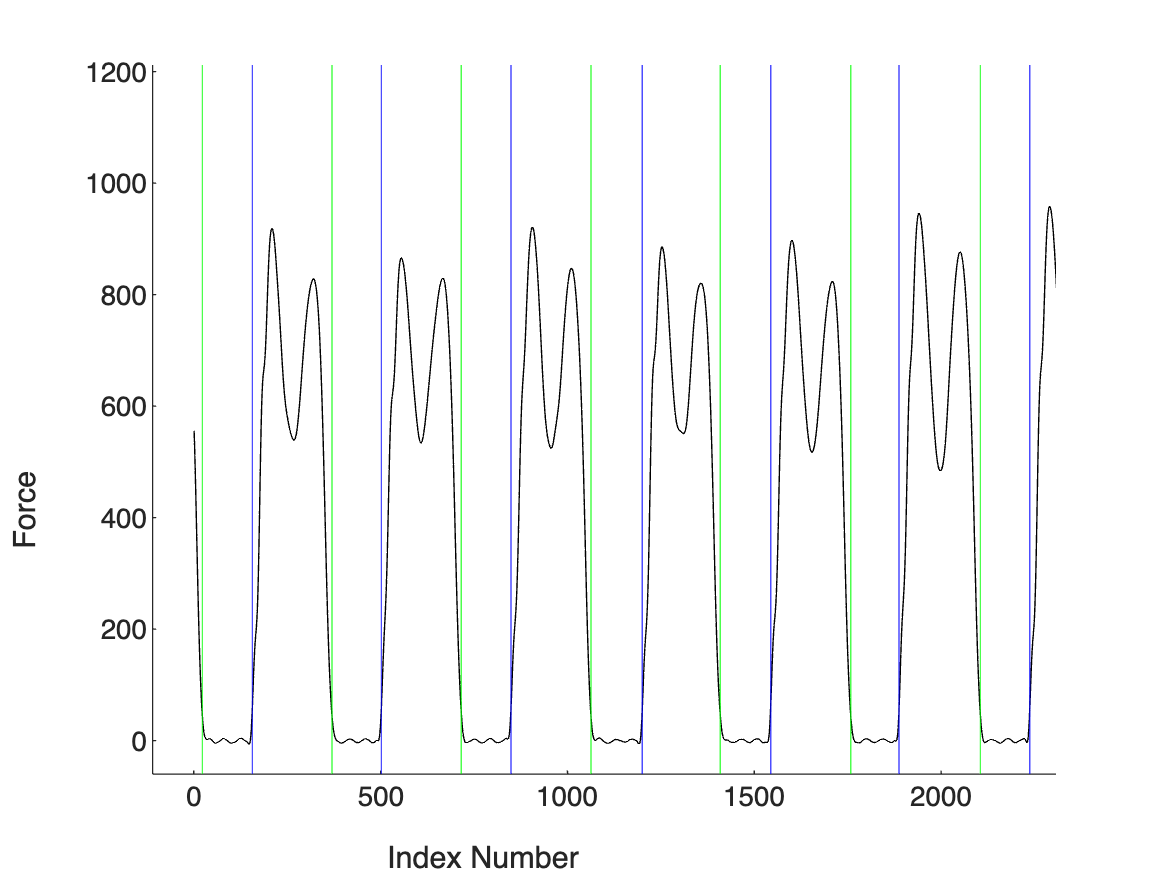

R_HeelStrikes   = GetHeelStrikes(D.R_F(:, 3));
R_ToeOffs       = GetToeOffs(D.R_F(:, 3));
figure; hold on
xline(R_HeelStrikes,'b')
xline(R_ToeOffs,'g')
plot(D.R_F(:,3),'k')
ylabel('Force')
xlabel('Index Number')

xlim([-110 2307])
ylim([-60 1212])

## 4.b

('SegmentDataByPhase'), that segments strides by heel strike.  

The function should take two inputs: 1) a list containing heel strike indices, and 3) the data we want to segment. It should have one output: a 101 x n matrix, where n is the number of strides. Each stride (heel strike to the following heel strike) gets its own column, and has been interpolated to be 101 datapoints, corresponding to the percentage of stride [0:1:100].  

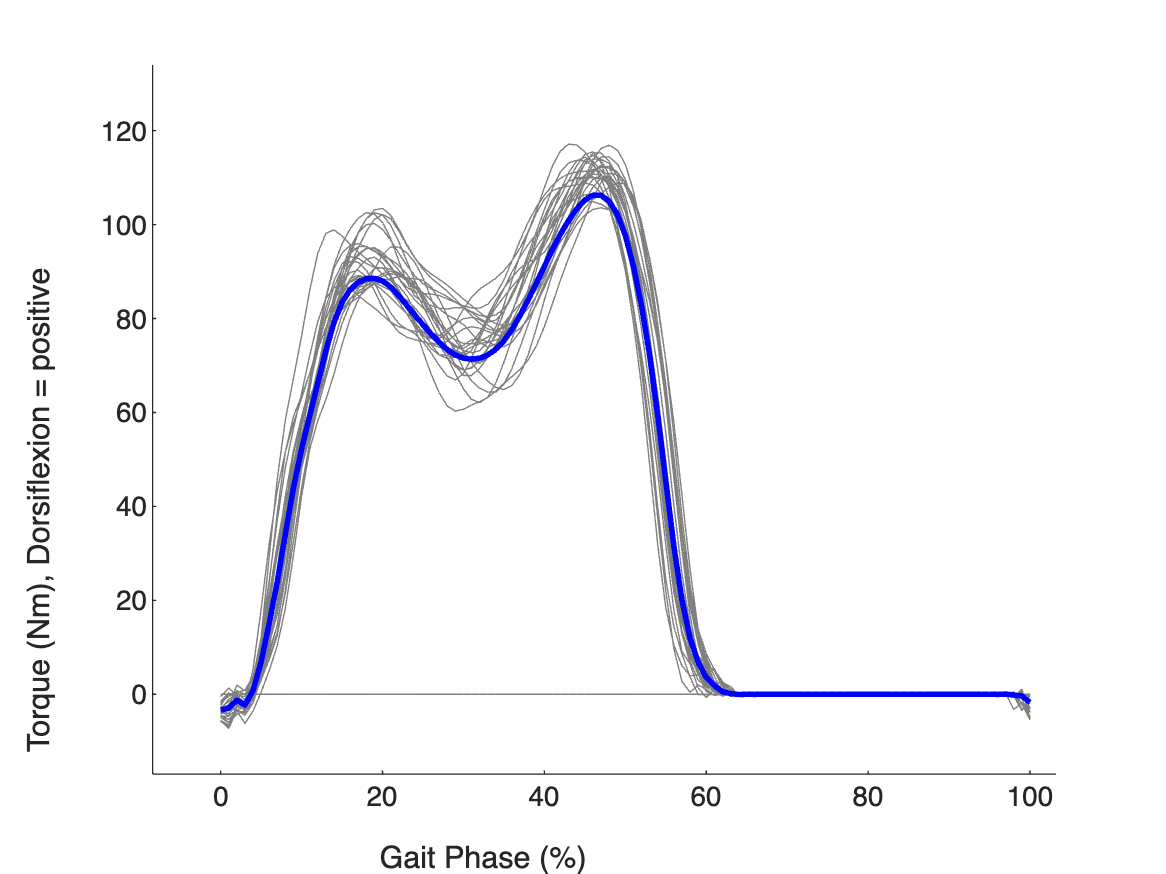

% plot the 25 strides of ankle torque.
gait_phase = 0:1:100;

r_ankle_angles = SegmentDataByPhase(R_HeelStrikes, R_Ankle_Angle);
r_ankle_torques = SegmentDataByPhase(R_HeelStrikes, R_Ankle_Torque);
mean_r_ankle_angle = mean(r_ankle_angles, 2);
mean_r_ankle_torque = mean(r_ankle_torques, 2);

figure; hold on
plot(gait_phase, r_ankle_torques, 'color', [0.5, 0.5, 0.5, 0.5])
plot(gait_phase, mean_r_ankle_torque, 'b', linewidth = 2)
ylabel('Torque (Nm), Dorsiflexion = positive')
xlabel('Gait Phase (%)')

xlim([-8.4 103.2])
ylim([-17 134])
zlim([-1.00 1.00])

## 4.c

**Plotting** the mean ankle angle vs mean ankle torque. In this case, define dorsiflexion *angle* as positive, and plantarflexion *torque* as positive (i.e., multiple mean ankle torque by -1). One reason we often do this is because the ankle behavior during gait is spring-like. To illustrate this, we have to describe the EXTERNAL moment (again, equal and opposite) that would cause the spring to deflect.  So this illustrates how, as the ankle is dorsiflexed, it resists with a plantarflexion torque. [5]

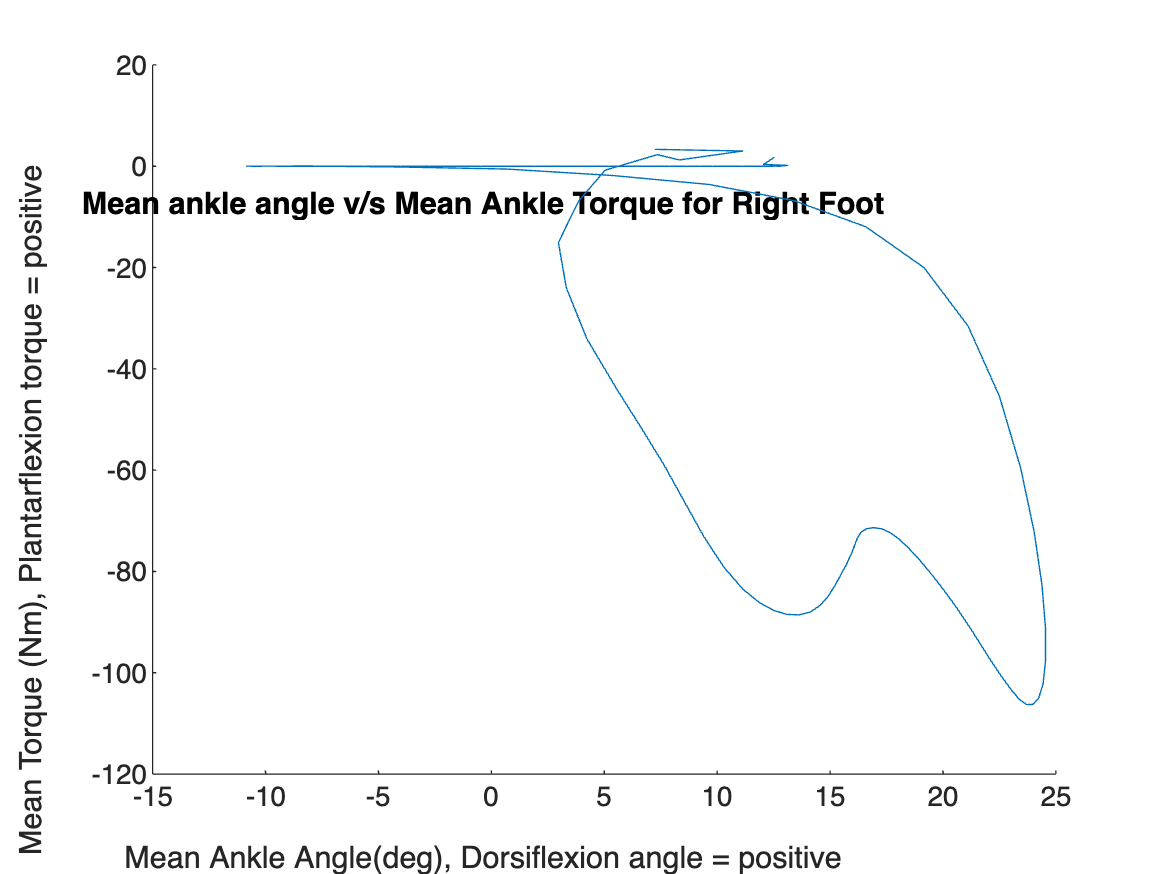

figure; hold on
plot(mean_r_ankle_angle,-1*(mean_r_ankle_torque))
title('Mean ankle angle v/s Mean Ankle Torque for Right Foot')
ylabel('Mean Torque (Nm), Plantarflexion torque = positive')
xlabel('Mean Ankle Angle(deg), Dorsiflexion angle = positive')

## 4.d

Cell sequentially loads and plots the slow, medium, and fast trials. 

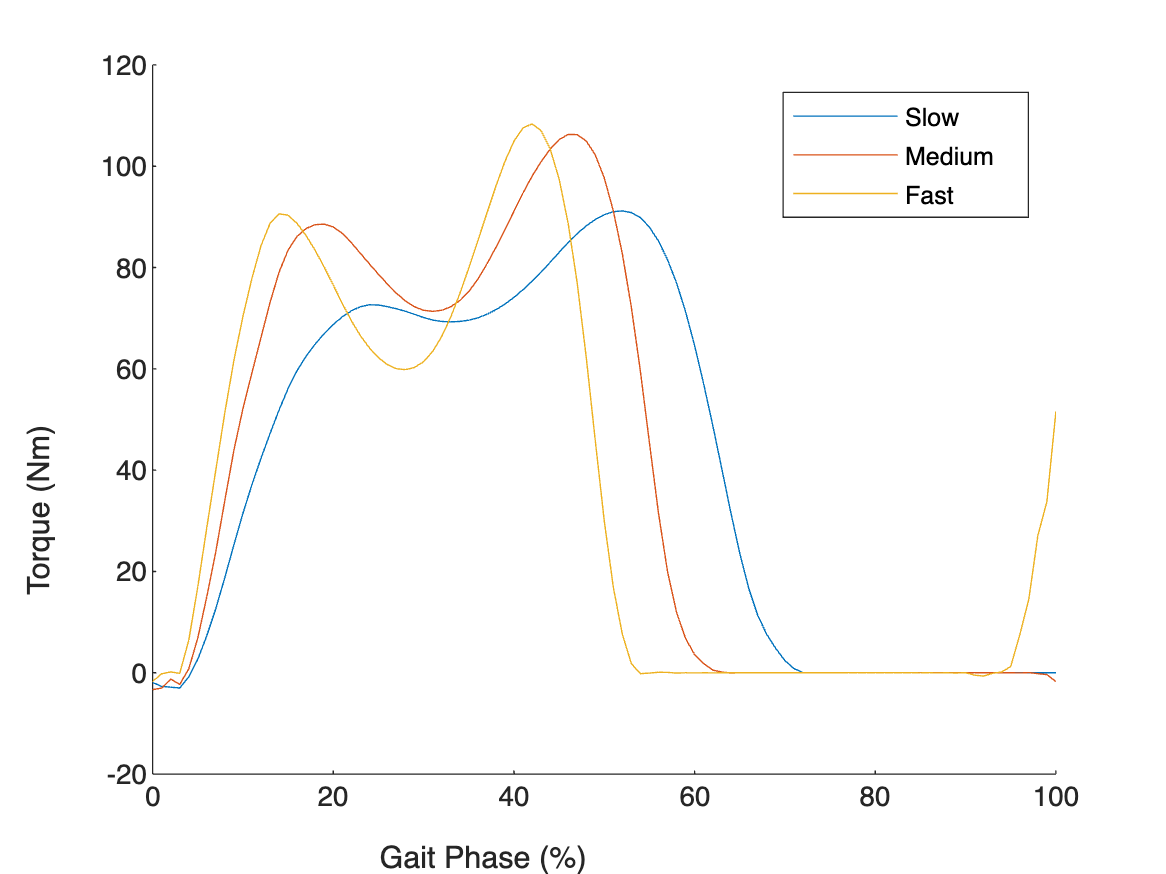

close all
filename  = ["0deg_.9ms_tracked", "0deg_1.2ms_tracked", "0deg_1.5ms_tracked"]; % Load the intermediate walking speed trial
for file_num = 1:3
    data = load(filename(file_num) + ".mat");
    temp_ = fieldnames(data);
    data = data.(temp_{1});
    fs_force    = data.Force.Frequency; % Forceplate sampling frequency
    fs_markers  = data.FrameRate; % Marker sampling frequency
    
    D   = RepackageMocapData(data, fs_force, fs_markers);

    R_Ankle_Angle = CalculateAnkleAngle(D.R_Knee_Lat, D.R_Ankle_Lat, D.R_Toe_Tip, D.R_Heel); % Only modify CalculateAnkleAngle function
    COP_relative_to_ankle_in_AP = D.R_COP(:,2) - D.R_Ankle_Lat(:,2);
    R_Ankle_Torque = CalculateAnkleTorque(D.R_F(:, 2), D.R_F(:,3), COP_relative_to_ankle_in_AP*0.001, D.R_Ankle_Lat(:,3)*0.001);
    R_Ankle_Torque(D.R_F(:,3)<50) = 0;
    R_HeelStrikes   = GetHeelStrikes(D.R_F(:, 3));
    
    gait_phase = 0:1:100;
    
    r_ankle_torques = SegmentDataByPhase(R_HeelStrikes, R_Ankle_Torque);
    mean_r_ankle_torque = mean(r_ankle_torques, 2);
    
    figure(1); hold on
    plot(gait_phase, mean_r_ankle_torque)
end
legend(["Slow", "Medium", "Fast"])
ylabel('Torque (Nm)')
xlabel('Gait Phase (%)')

## **5.a**

**Why might the ankle torque be increasing with increasing speed?** 

*1) The ankle torque increases as the speed increases due to the following reasons:*

*    a) It can be seen that the late stance phase occurs earlier during the gait cycle, and there is not enough time for the loading phase, which is compensated by higher torque.*

*    b) At higher speeds, the center of pressure also shifts forward which means joint torque at angle to balance the ground reaction forces will also be higher. *

*    c) At faster speeds, the momentum is also higher which means the possibility of instability due minor imbalanced forces also increases, which is again to be conteracted by the angle torque.*

*    d) Simultaneously, the ankle may stiffen up for maintain proper gait while moving quickly, this may command more torque as seen in the figure.*

*    e) It is to be noted that this figure shows torque in terms of phase of gait and not seconds; which does not properly convey that the torque increase may also be due to more "muscle activation" during brisk walking. *

## 5.b

**How might you adapt a prosthesis or exoskeleton controller to change with speed?**

*1) From the previous answer, an important characteristic of the ankle is variability in its stiffness, similarly an exoskeleton or a prosthetic needs to have the variability in stiffness to adapt dynamic change in speeds.*

*2) It can be seen that the torque curve is steeper for higher walking speeds, which means the ankle angle change might be a very instanteous yet smooth function and this should be facilitated by the exoskeleton.*

*3) The controller should be able to accurately measure and subsequently predict the torques and ankle angles for the correct gait phase.*

*4) The actuator  should be selected and programmed  such that it should be able provide quick and high amount of assistive or resistive torque as required for rapid acceleration or deceleration.*

*5) Another significant characteristic of the ankle joint is the shock absorption provided with the the help of achilles tendon, which could aid in absorption of ground forces while maintaining upper body stability during rapid gait changes; and this characteriestic should be possessed by a prosthetic.*